# volatility forecasting using different models

clc,clear
addpath("data_Files")
addpath("m_Files_ClusterPartition")
addpath("m_Files_Color")
addpath("m_Files_Color/colormap")
dax=readtable("DAX.csv","VariableNamingRule","preserve");
dax(:,1:2)=[];
dax.Properties.VariableNames={'date','open','high','low',...
    'close','trade_amount','trade_volume'};
logret=price2ret(dax.close);
timeline=dax.date(2:end);

## forecast 2007

forecast_year=2007;
oos_index=year(timeline)==forecast_year;

time_oos=timeline(oos_index);
n=numel(time_oos);
oos_start=find(oos_index>0);

v_act=(logret(oos_index)).^2;
vf_cpgarch=zeros(size(time_oos));
vf_cpgarchitr=zeros(size(time_oos));
vf_garch=zeros(size(time_oos));
vf_egarch=zeros(size(time_oos));
vf_gjrgarch=zeros(size(time_oos));
vf_rsgarch=zeros(size(time_oos));

for i=1:n
    ret=logret(oos_start+i-1-250:oos_start+i-1);

    % garch
    mdl=garch("ARCHLags",1,"GARCHLags",1,"Offset",NaN);
    Est_mdl=estimate(mdl,ret,"Display","off");
    vf_garch(i)=forecast(Est_mdl,1,ret);
    % cpgarch
    v_garch=infer(Est_mdl,ret);
    [LB,J,D]=Fisher_div_sqr(v_garch,1);
    K=OptimalClusterNumber(v_garch,LB);
    if K==numel(v_garch)
        K=K-1;
    end
    v_cpgarch=Vol_ClusterPartition(v_garch,K,J);
    vf_cpgarch(i)=v_cpgarch(end);
    % cpgarch_iteration

    % egarch
    mdl=egarch("ARCHLags",1,"GARCHLags",1,"Offset",NaN);
    Est_mdl=estimate(mdl,ret,"Display","off");
    vf_egarch(i)=forecast(Est_mdl,1,ret);
    % gjrgarch
    mdl=gjr("ARCHLags",1,"GARCHLags",1,"Offset",NaN);
    Est_mdl=estimate(mdl,ret,"Display","off");
    vf_gjrgarch(i)=forecast(Est_mdl,1,ret);
    % re-garch
    addpath("m_Files_swgarch\")
    [estimation, probabilities, ~] = swgarch(ret, 2, 'NORMAL',...
                'HAAS','CONS', {'YES',[]}, [0.1 0.1 0.82;0.05 0.05 0.7], ...
                [0.8 0.2;0.2 0.8], [], []);
    vf=swgarch_forecast(1,2,estimation.garch, ...
        estimation.transM,'INDEP','NORMAL',[],0,ret,estimation.H, ...
        probabilities);
    vf_rsgarch(i)=vf.vH;
    rmpath("m_Files_swgarch\")
end

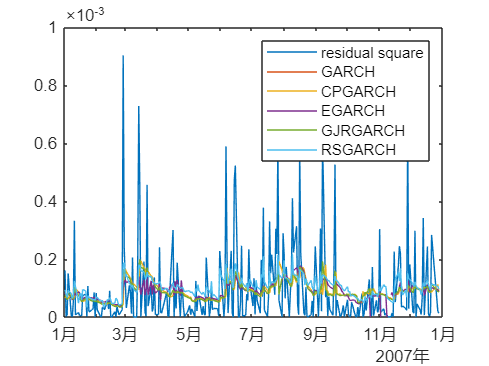

figure;
plot(time_oos,v_act,'LineWidth',1,'color',addcolor(185));
figure;
plot(time_oos,[v_act,vf_garch,vf_cpgarch,vf_egarch,vf_gjrgarch, ...
    vf_rsgarch]);
legend("residual square","GARCH","CPGARCH","EGARCH","GJRGARCH", ...
    "RSGARCH");

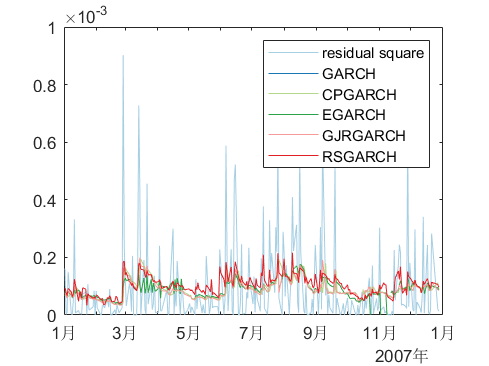

figure;
col=Paired(6);
plot(time_oos,v_act, "Color",col(1,:));hold on
plot(time_oos,vf_garch, "Color",col(2,:));
plot(time_oos,vf_cpgarch,"Color",col(3,:));
plot(time_oos,vf_egarch, "Color",col(4,:));
plot(time_oos,vf_gjrgarch, "Color",col(5,:));
plot(time_oos,vf_rsgarch, "Color",col(6,:));
legend("residual square","GARCH","CPGARCH","EGARCH","GJRGARCH", ...
    "RSGARCH");

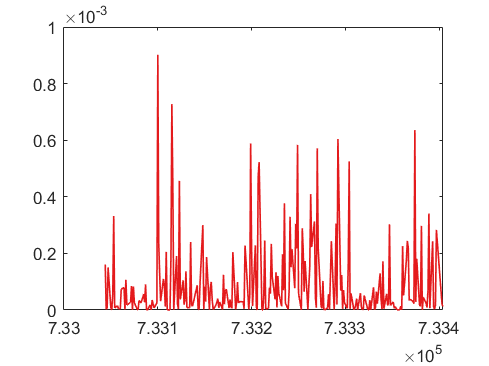

figure;
plot(datenum(time_oos),v_act,'LineWidth',1,'color',addcolor(185));

% dateaxis("x",12);